%calculating the mean first passage time analytically/numerically 
%to investigate effect of multiple invader-substrate mismatches on RNA/DNA
%toehold exchange kinetics including spontaneous incumbent and invader
%dissociation

b = 20 %define branch migration domain length

b = 20

g = 7 %define invader toehold length

g = 7

g2 = 2 %define incumbent toehold length

g2 = 2


bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


m = zeros(1, 4)

m =      0     0     0     0


m(1) = 2 %define position of first mismatch 

m =      2     0     0     0



R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K 

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.5*R*temp

dGrd = -0.2962

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(4,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(4, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(4, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(4, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(4, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(4, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through number of mismatches 
for ind = 2:5
    %loop through position of mismatches
    for pos = m(ind-1)+1:b
        m(ind) = pos
        
        trans_state = (- dGbp  - dGrd)*(b+ g-1)
        react_coord = zeros(1, b-1)
        %loop through states after mismatch and define free energy (in
        %terms of invader dissociation)
        for no = ind:-1:1
            if no == ind
                for state = 1:b-m(no)
                    react_coord(state) = (-dGbp - dGrd)*(state) + dGmm*no;
                end
            else 
                for state = b-m(no+1)+1:b-m(no)
                    react_coord(state) = (-dGbp - dGrd)*(state) + dGmm*no;
                end
            end
        end
        %loop through states before mismatch and define free energy (in
        %terms of invader dissociation)
        for state = b-m(1)+1:b-1
            react_coord(state) = (- dGbp - dGrd)*(state)
        end

        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Crm = k_bp* exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added + dGrd
        k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)) %I have added + dGrd
        k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_DEij = k_bp * exp(dGbp/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp * exp(dGbp/(R*temp));
        k_FE = 0
        k_FF = 1    
    
    
        if g == 1
            %create arrays of forward and reverse transition rates for
            %mismatch-free system
            Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
            %define spontaneous invader dissociation rates for
            %mismatch-free system
            Koff_inv_perf = [repmat(0, [1, g2+1])];
            for n = b+g-1:-1:g+1
                Koff_inv_perf = horzcat(Koff_inv_perf, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff_inv_perf = horzcat(Koff_inv_perf, [0, 0])
            
            %create arrays of forward and reverse transition rates
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
            for no = 1:ind
                if m(no) == b
                    Kb(b + g2 - m(no) + 1) = k_Crm_end
                else
                    Kb(b + g2 - m(no) + 1) = k_Crm
                end
            end
   
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])];
            for n = g2 + 1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
            
            %define spontaneous invader dissociation rates for mismatch
            %system
            Koff_inv = [repmat(0, [1, g2+1])];
            for n = 1:b-1
                Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp-dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
            end
            Koff_inv = horzcat(Koff_inv, [0, 0])
        
        
        else
            %create arrays of forward and reverse transition rates for
            %mismatch-free system
            Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
            %define spontaneous invader dissociation for mismatch-free
            %system 
            Koff_inv_perf = [repmat(0, [1, g2+1])];
            for n = b+g-1:-1:g+1
                Koff_inv_perf = horzcat(Koff_inv_perf, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff_inv_perf = horzcat(Koff_inv_perf, [repmat(0, [1, g+1])])
        
            %create arrays of forward and reverse transition rates for
            %mismatch system
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
            for no = 1:ind
                if m(no) == b
                    Kb(b + g2 - m(no) + 1) = k_Crm_end
                else 
                    Kb(b + g2 - m(no) + 1) = k_Crm
                end
            end
        
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])]; 
            for n = g2 + 1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
            
            %define spontaneous invader dissociation rates for
            %mismatch system
            Koff_inv = [repmat(0, [1, g2+1])];
            for n = 1:b-1
                Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp-dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
            end
            Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
        
        
        end
        
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        j_cycle = zeros(1,numel(Kf));
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state for mismatch system
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn);
            j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
        end
        
        Pn_jN_1_perf = zeros(1,numel(Kf_perf))
        jn_jN_1_perf = zeros(1,numel(Kf_perf))
        j_cycle_perf = zeros(1,numel(Kf_perf));
        Pn_jN_1_perf (1) = 0;
        jn_jN_1_perf (1) = 1;
        
        %calculate flux between each state for mismatch-free system
        for Pn = 2:numel(Kf_perf)
            Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
            jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + (Koff(Pn) + Koff_inv_perf(Pn)) * Pn_jN_1_perf(Pn);
            j_cycle_perf(Pn) = Pn_jN_1_perf(Pn)*Koff_inv(Pn);
        end
    
        j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end))%successful flux for mismatch system
        first_pass_time (ind-1, pos) = (1/j_disp)*sum(Pn_jN_1)%first passage time for mismatch system
        %first_pass_time (ind - 1, pos) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
        k_eff (ind-1, pos) = 1/(first_pass_time (ind - 1, pos)*(5*10^-8));%effective rate constant for mismatch system
        prob_unbound(ind-1, pos) = Pn_jN_1(end)/sum(Pn_jN_1)%probability of being in unbound state for mismatch system
    
        j_disp_perf = jn_jN_1_perf(end-1) - sum(j_cycle_perf(1:end))%successful flux for mismatch-free system
        first_pass_time_perf (ind-1, pos) = (1/j_disp_perf)*sum(Pn_jN_1_perf)%first passage time for mismatch-free system
        %first_pass_time_perf (ind-1, pos) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf)
        k_eff_perf (ind - 1, pos) = 1/(first_pass_time_perf (ind-1, pos)*(5*10^-8));%effective rate constant for mismatch-free system
        prob_unbound_perf(ind-1, pos) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%probability of being in unbound state for mismatch-free system
    end
    m(ind) = m(ind-1) + 3; %introduce space between the mismatches
end

m =      2     3     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   39.8820   41.6711   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586   36.0351  738.4066    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time = 	1.0e+05 *

         0         0    1.4315         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.9215

first_pass_time_perf =          0         0    5.5811         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     4     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   39.8820   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586   36.0351    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time = 	1.0e+05 *

         0         0    1.4315    0.8672         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0376

first_pass_time_perf =          0         0    5.5811    5.2630         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     6     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0435

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     7     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     8     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     9     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    10     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    11     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    12     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    13     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0445

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    14     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0532

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    15     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.1557

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    16     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   14.5736   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 3.3134

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032    0.0013         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    17     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   12.7845   14.5736   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 15.3344

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032    0.0013    0.0003         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    18     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   10.9954   12.7845   14.5736   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 117.7514

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032    0.0013    0.0003    0.0002         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    19     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452    9.2063   10.9954   12.7845   14.5736   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 590.5892

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032    0.0013    0.0003    0.0002    0.0002         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    20     0     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.4171    9.2063   10.9954   12.7845   14.5736   16.3628   18.1519   19.9410   21.7301   23.5192   25.3084   27.0975   28.8866   30.6757   32.4648   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 23.8004

first_pass_time =          0         0    1.4315    0.8672    0.5259    0.3189    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0095    0.0056    0.0032    0.0013    0.0003    0.0002    0.0002    0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0436

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     6     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   40.1427   41.9318   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0560    1.1465    0.0018    0.0000    0.0001    0.0011    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.8539

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     7     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   40.1427   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305   55.9520    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0340

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     9     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    10     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    11     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    12     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    13     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0445

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    14     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0532

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    15     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.1557

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    16     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 3.3134

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401    0.0148         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    17     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 15.3344

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401    0.0148    0.0021         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    18     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 117.7514

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401    0.0148    0.0021    0.0006         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    19     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 590.5892

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401    0.0148    0.0021    0.0006    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    20     0


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    13.0452   14.8343   16.6234   18.4125   20.2017   21.9908   23.7799   25.5690   27.3581   29.1473   30.9364   32.7255   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 23.8004

first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2655    2.5807    1.5631    0.9460    0.5718    0.3448    0.2071    0.1236    0.0726    0.0401    0.0148    0.0021    0.0006    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0433

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     9


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   40.4033   42.1924   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0042    0.0869    1.7802    0.0027    0.0000    0.0001    0.0018    0.0000    0.0001    0.0011    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0439

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.7501

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    10


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   40.4033   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397   86.8771    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0286

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    12


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0438

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    13


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0446

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    14


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0532

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    15


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.1557

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    16


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 3.3134

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530    0.0192         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    17


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 15.3344

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530    0.0192    0.0023         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    18


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 117.7514

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530    0.0192    0.0023    0.0003         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    19


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 590.5892

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530    0.0192    0.0023    0.0003    0.0002         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    20


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    18.6732   20.4623   22.2514   24.0406   25.8297   27.6188   29.4079   31.1971   32.9862   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 23.8004

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2669    0.7634    0.4601    0.2761    0.1645    0.0965    0.0530    0.0192    0.0023    0.0003    0.0002    0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0428

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11    12


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   35.2966   37.0857   38.8749   40.6640   42.4531   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0003    0.0066    0.1349    2.7642    0.0042    0.0000    0.0001    0.0027    0.0000    0.0001    0.0018    0.0000    0.0001    0.0011    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.4037

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396         0         0         0         0         0         0         0         0


j_disp_perf = 1.5975

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0


m =      2     5     8    11    13


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   35.2966   37.0857   38.8749   40.6640   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0008    0.0157    0.3213    6.5830  134.8947    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.2581

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396         0         0         0         0         0         0         0


j_disp_perf = 2.0208

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0


m =      2     5     8    11    14


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   35.2966   37.0857   38.8749   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0008    0.0157    0.3213    6.5830    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.1789

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131         0         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396         0         0         0         0         0         0


j_disp_perf = 2.0411

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0


m =      2     5     8    11    15


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   35.2966   37.0857   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0008    0.0157    0.3213    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.2281

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833         0         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396         0         0         0         0         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0


m =      2     5     8    11    16


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   35.2966   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0008    0.0157    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 3.3535

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833    0.2515         0         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514    5.2513         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0


m =      2     5     8    11    17


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   33.5075   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0008    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 15.3551

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833    0.2515    0.0284         0         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514    5.2513    5.2513         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0


m =      2     5     8    11    18


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   31.7184   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 117.7626

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833    0.2515    0.0284    0.0020         0         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514    5.2513    5.2513    5.2513         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0


m =      2     5     8    11    19


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    29.9293   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 590.6041

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833    0.2515    0.0284    0.0020    0.0005         0


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396         0


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514    5.2513    5.2513    5.2513    5.2513         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0


m =      2     5     8    11    20


trans_state = 46.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    24.3012   26.0904   27.8795   29.6686   31.4577   33.2468   35.0360   36.8251   38.6142   34.7753   36.5644   38.3535   34.5146   36.3037   38.0929   34.2540   36.0431   37.8322   33.9933


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017         0         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0101    0.2069    4.2397    0.0065    0.1333    2.7305    0.0042    0.0858    1.7586    0.0027    0.0553    1.1326    0.0017         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 23.8009

first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1492    1.9891    1.2131    0.6833    0.2515    0.0284    0.0020    0.0005    0.0005


prob_unbound =          0         0    0.1397    0.1397    0.1397    0.1398    0.1399    0.1400    0.1403    0.1406    0.1413    0.1424    0.1442    0.1473    0.1532    0.1734    0.2687    0.3311    0.3364    0.3367
         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1397    0.1397    0.1397    0.1397
         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396
         0         0         0         0         0         0         0         0         0         0         0    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396    0.1396


j_disp_perf = 2.0421

first_pass_time_perf =          0         0    5.5811    5.2630    5.2484    5.2477    5.2477    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476
         0         0         0         0         0    5.7846    5.2722    5.2496    5.2485    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484    5.2484
         0         0         0         0         0         0         0         0    6.1275    5.2864    5.2513    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496    5.2496
         0         0         0         0         0         0         0         0         0         0         0    6.7131    5.3067    5.2539    5.2514    5.2513    5.2513    5.2513    5.2513    5.2513


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992


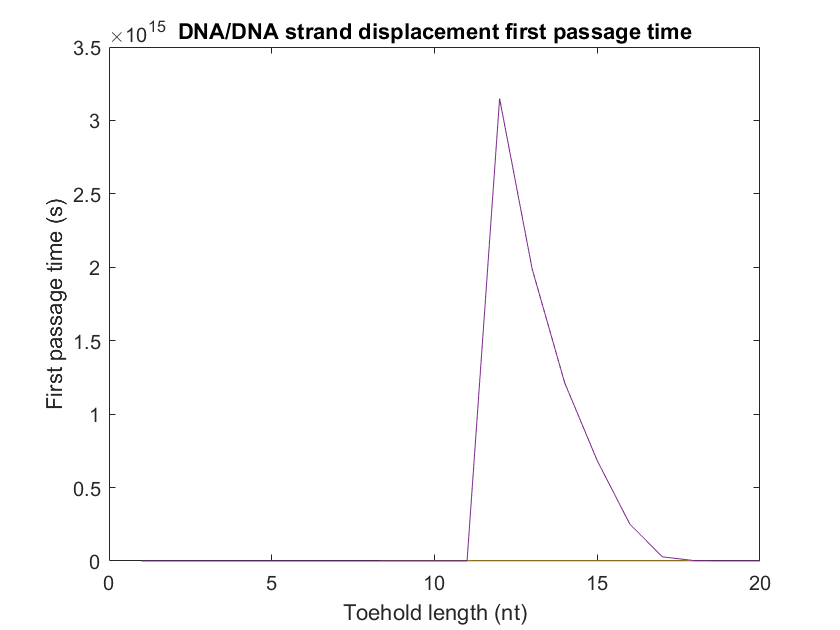

plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

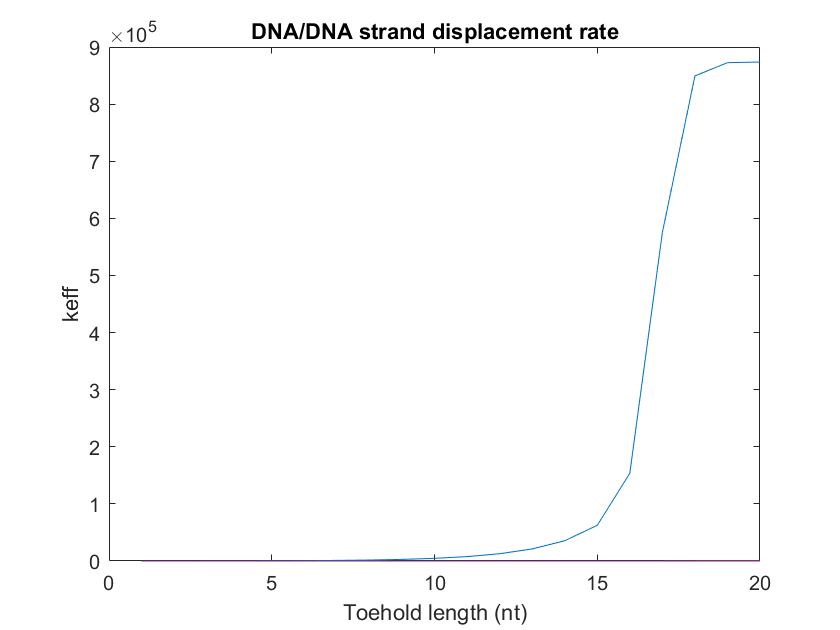


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

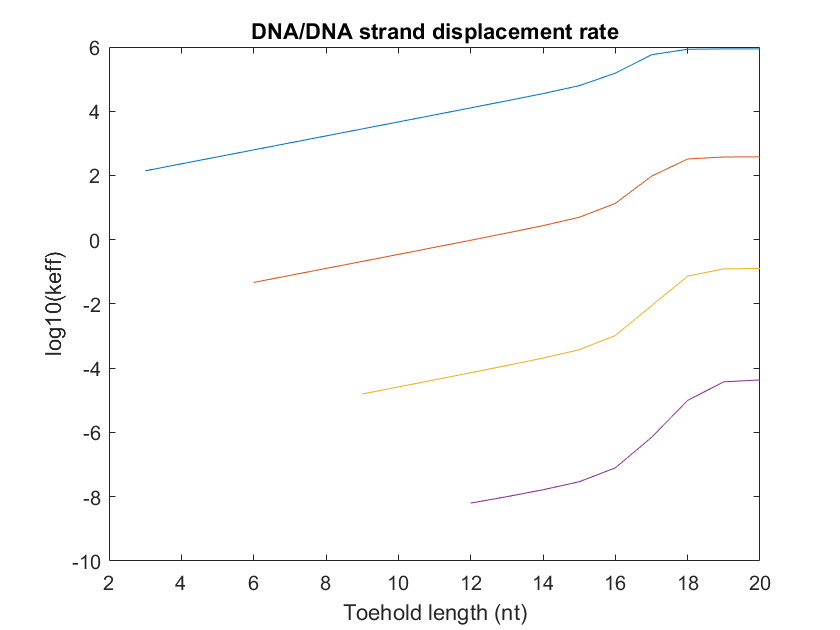


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

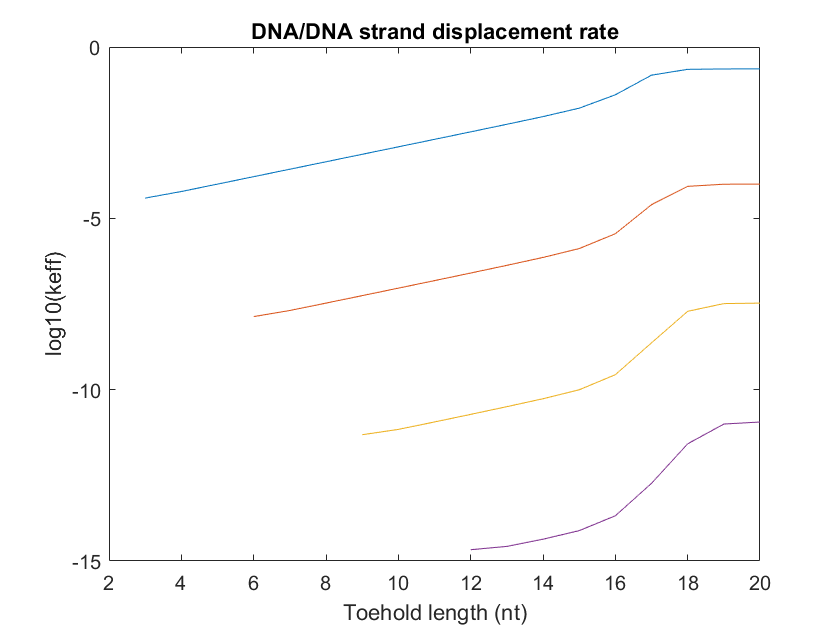


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 


ax = gca;
dark_blue = 1/255*[31,120,180];
medium_blue = 1/255*[95, 141, 211]

medium_blue =     0.3725    0.5529    0.8275


light_blue  = 1/255*[146,197,222];
rred = 1/255*[202,0,32];
maroon = 1/255*[170, 0, 0]

maroon =     0.6667         0         0


teal = 1/255*[55, 200, 171]

teal =     0.2157    0.7843    0.6706


purple = [0.4940, 0.1840, 0.5560]

purple =     0.4940    0.1840    0.5560


indigo = 1/255*[198, 175, 233]

indigo =     0.7765    0.6863    0.9137


colour = [[rred]; [purple]; [dark_blue];[light_blue]]

colour =     0.7922         0    0.1255
    0.4940    0.1840    0.5560
    0.1216    0.4706    0.7059
    0.5725    0.7725    0.8706



for dG = 1:4
    plot(1:20, log10(k_eff(dG, :)./k_eff_perf(dG, :)), 'Color', colour(dG, :), 'linewidth', 2)
    hold on
    scatter(1:20, log10(k_eff(dG, :)./k_eff_perf(dG, :)),[], colour(dG, :),  'filled', 'HandleVisibility', 'off')
end
legend('2 MM','3 MM', '4 MM','5 MM', 'location', 'southwest')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [2 20]
             YLim: [-15 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [2 20]
             YLim: [-15 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [-15 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


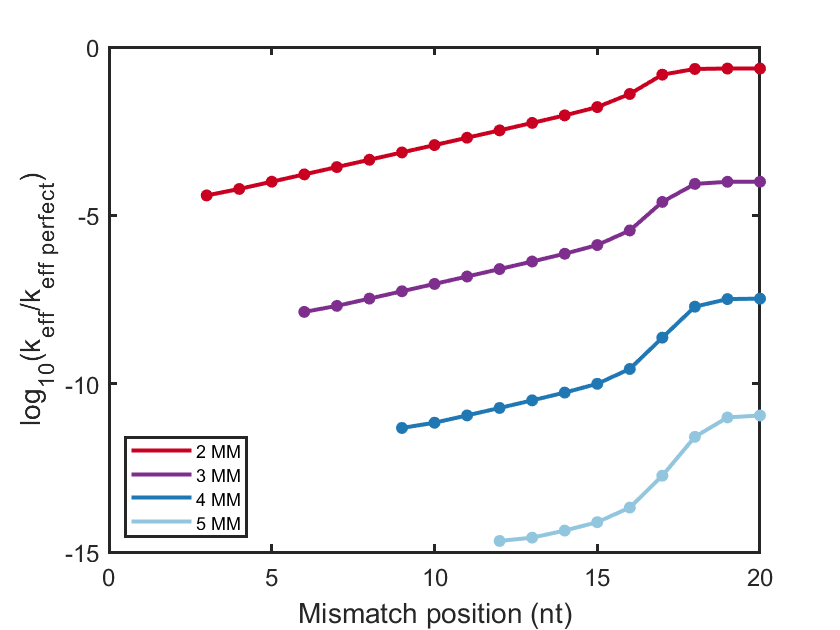

xlabel('Mismatch position (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f/k_e_f_f_ _p_e_r_f_e_c_t)', 'FontSize', 14)
hold off 